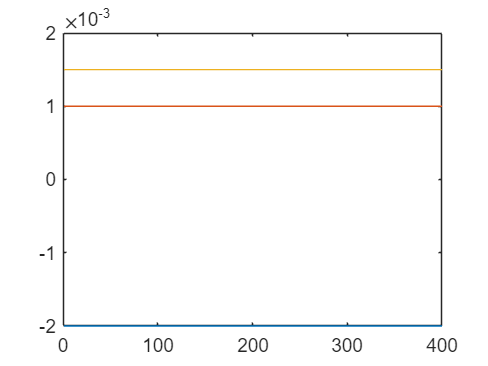

qd = quaternion(Rd,'rotmat','point');
qd2 = rotm2quat(Rd);

dt = 1/200;  % your time step
% q1=qd(100,:);
% q2=qd(101,:);
% q2*conj(q1)
% conj(q1)*q2
% wq=2/dt*conj(q1)*(q2-q1)
% 
% wq1=2/dt*conj(q1)*(-q2-q1)
% 
% wq2=2/dt*conj(-q1)*(q2+q1)

omega = estimate_angular_velocity(qd, dt);
omega1 = estimate_angular_velocity1(qd, dt);
% Display the angular velocity
plot(omega-wd(1:end-1,:));

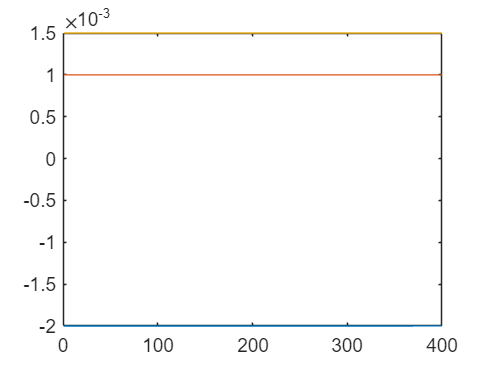


plot(omega1-wd(1:end-1,:));

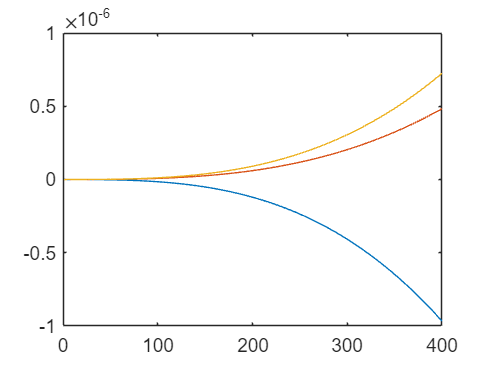

plot(omega-omega1)

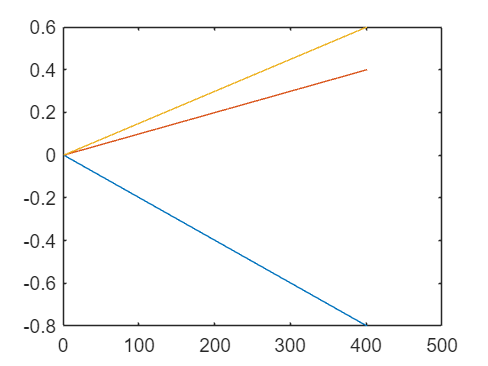

plot(wd);

function omega = estimate_angular_velocity(qd, dt)
    % qd: Nx4 matrix, each row is a quaternion [q0, q1, q2, q3]
    % dt: time step
    % omega: (N-1)x3 matrix, each row is the angular velocity vector

    N = size(qd, 1);
    omega = zeros(N-1, 3);

    for i = 1:N-1
        q_t = qd(i, :);
        q_t_dt = qd(i+1, :);
        
        % Calculate the quaternion conjugate
        q_t_conj = conj(q_t);
        
        % Calculate the quaternion difference delta_q
        delta_q = q_t_dt*q_t_conj;
        
        % Extract vector part and scalar part
        tmp = compact(delta_q);
        v = tmp(2:4);
        delta_q_0 = tmp(1);
        v_norm = norm(v);
        
        % Calculate angular velocity
        if v_norm > 0
            omega(i, :) = (2 / dt) * acos(delta_q_0) * (v / v_norm);
        else
            omega(i, :) = [0, 0, 0];
        end
    end
end

function omega = estimate_angular_velocity1(qd, dt)
    % qd: Nx4 matrix, each row is a quaternion [q0, q1, q2, q3]
    % dt: time step
    % omega: (N-1)x3 matrix, each row is the angular velocity vector

    N = size(qd, 1);
    omega = zeros(N-1, 3);

    for i = 1:N-1
        q_t = qd(i, :);
        q_t_dt = qd(i+1, :);
        
        
        wq=2/dt*conj(q_t_dt)*(q_t_dt-q_t);
        tmp=compact(wq);
        omega(i,:)=tmp(2:4);
    end
end

